# Landing a Probe on Mars

## Task 1

The velocity v of a probe falling towards Mars is governed by the differential equation

dv/dt=g−Dv2

where D=3.3×10−5 m-1, g=3.72 m/s2, v is in m/s, and t is in seconds. The probe enters the atmosphere with an initial velocity of 6 km/s (6000 m/s).

Task

Find and plot the probe's velocity from t=0 to 120 seconds. 

Use `ode45` to solve the ODE. Define the time interval and initial condition, and create a local ODE function `fallingbody` at the bottom of the script to implement the ODE. 

Assign the outputs to the variables `tSol` and `vSol`. Then plot `vSol` as a function of `tSol`.

Recall that the number 3.3×10−5 can be written in MATLAB as `3.3e-5`.

Find and plot the probe's velocity.

*Remember to define your ODE function at the bottom of this script.*

tRange=[0 120]

tRange =      0   120


v0=6000

v0 = 6000

[tSol,vSol]=ode45(@fallingbody,tRange,v0)

tSol =          0
    0.2545
    0.5090
    0.7636
    1.0181
    1.7041
    2.3900
    3.0760
    3.7620
    4.6385


vSol = 1.0e+03 *

    6.0000
    5.7130
    5.4523
    5.2145
    4.9966
    4.4902
    4.0784
    3.7381
    3.4503
    3.1398


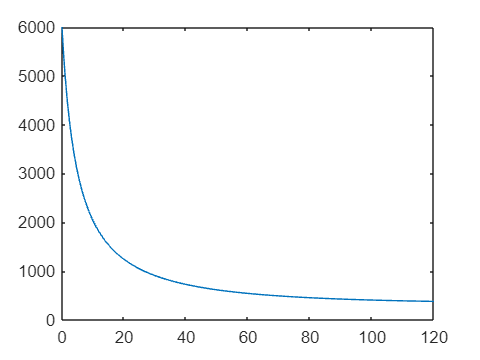

plot(tSol,vSol)

## Task 2

Find the probe's velocity after 120 seconds. Assign it to the variable `v120`.

 You may want to leave off the semicolon to display the result.

v120=vSol(end)

v120 = 380.6347

## Further Practice

In just two minutes, the probe has slowed from 6000 m/s to 380 m/s.

The probe's *terminal velocity* is reached when the gravitational and drag forces are balanced, so the  drag force cannot slow it down further. Here, the terminal velocity is √g/D≈ 336 m/s. About how long does it take for the probe to slow down to 336 m/s?

Since the velocity is only 380 m/s after 120 seconds, you'll need to solve the ODE on a larger time interval.

`sol` `=` `ode45``(``@``fallingbody``,``[``0` `1000``]``,``v0``)``;`

Then you can evaluate `sol` at multiple times until the result is close to 336 m/s.

`deval``(``sol``,``200``)`

`deval``(``sol``,``400``)`

`deval``(``sol``,``350``)`

Alternatively, if you are familiar with the `fzero` function, you could use it to find when `sol` evaluates to 336:

`sol` `=` `ode45``(``@``fallingbody``,``[``0` `1000``]``,``v0``)``;`

`tTermVel` `=` `fzero``(``@``(``t``)` `deval``(``sol``,``t``)` `-` `336``,` `300``)`

sol = ode45(@fallingbody,[0 1000],v0)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 1.0181 3.7620 7.2681 12.2757 19.2590 28.9895 42.4229 60.7050 85.0527 116.6013 156.3616 205.4685 265.7865 340.8287 437.0820 537.0820 637.0820 737.0820 837.0820 937.0820 1000]
          y: [6000 4.9966e+03 3.4503e+03 2.4763e+03 1.7716e+03 1.2776e+03 932.8741 696.7532 540.0792 441.5586 384.5390 355.1806 342.2004 337.4558 336.0930 335.8095 335.7599 335.7508 335.7492 335.7489 335.7488 335.7488]
      stats: [1×1 struct]
      idata: [1×1 struct]


tTermVel = fzero(@(t) deval(sol,t) - 336, 300)

tTermVel = 353.6714

## Task 1 (continued)

Define the ODE function to solve    with *D* = `3.3e-5` and *g* = `3.72`. 

function dvdt=fallingbody(t,v)
D=3.3e-5;
g=3.72;
dvdt=g-D.*v.^2;
end